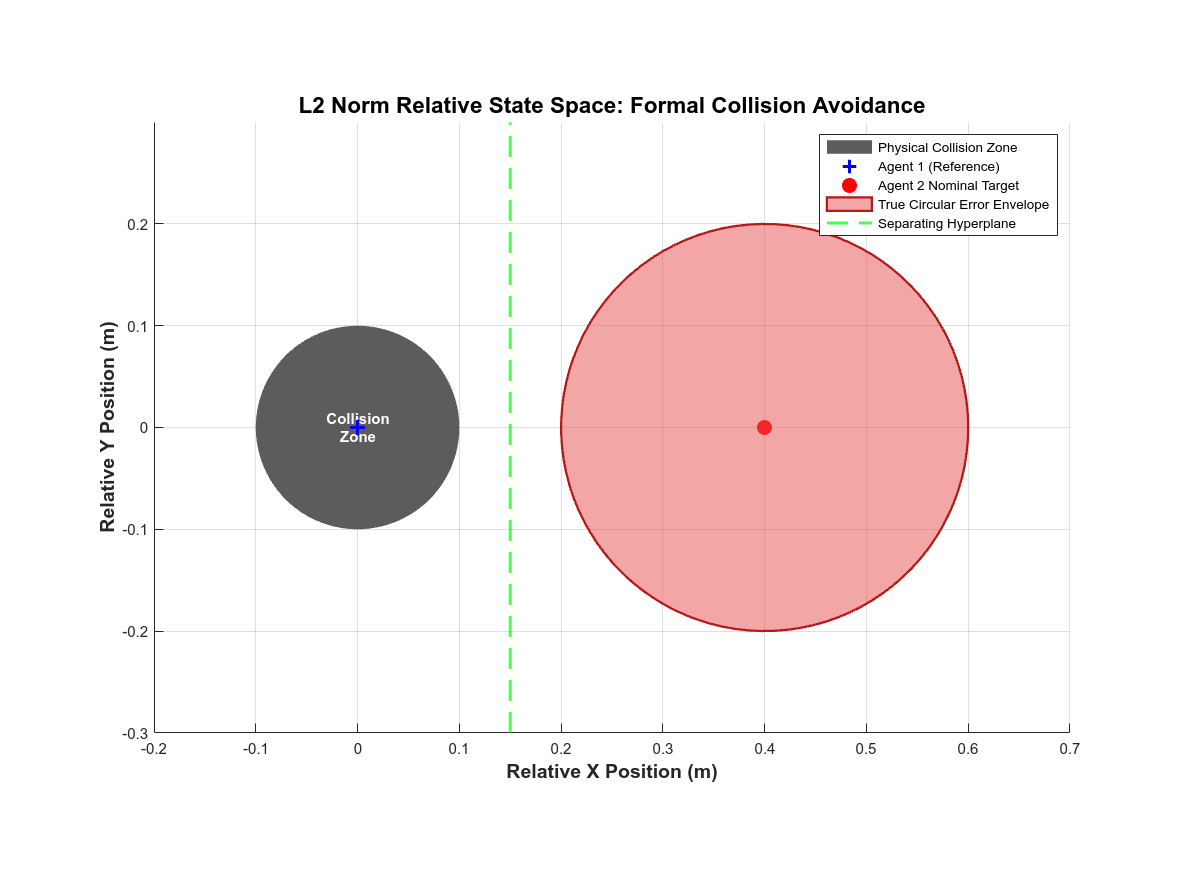

% =========================================================================
% 多机协同碰撞空间形式化安全验证 (L2 欧几里得空间精确版)
% 目标：剔除 Zonotope 的方形过度保守性，还原真实的圆形相对误差包络
% =========================================================================
clear; clc; close all;

%% 1. 定义物理与几何约束参数
d_apf_min = 0.4;        % APF名义最小挤压距离 (0.4m)
tube_radius = 0.1;      % 单机最大误差半径 (0.1m)
drone_radius = 0.05;    % Crazyflie 2.1 的物理半径 (5cm)

% 相对坐标系下：将无人机 1 固定在原点
target_pos_rel = [d_apf_min, 0]; % 无人机 2 的相对目标位置

%% 2. 终极绘图
figure('Name', 'Euclidean Relative Safety Verification', 'Position', [100, 100, 800, 600]);
hold on; grid on; axis equal;

% --- 1. 绘制绝对物理碰撞死区 (Minkowski Sum of 2 physical drones) ---
% 如果相对距离 < 0.1m (5cm + 5cm)，则发生物理碰撞
theta = linspace(0, 2*pi, 100);
collision_radius = drone_radius * 2; 
collision_x = collision_radius * cos(theta);
collision_y = collision_radius * sin(theta);
fill(collision_x, collision_y, [0.2, 0.2, 0.2], 'FaceAlpha', 0.8, 'EdgeColor', 'none');
text(0, 0, {'Collision', 'Zone'}, 'Color', 'w', 'HorizontalAlignment', 'center', 'FontWeight', 'bold');

% --- 2. 绘制目标的相对位置 ---
plot(0, 0, 'b+', 'MarkerSize', 10, 'LineWidth', 2);
plot(d_apf_min, 0, 'ro', 'MarkerSize', 8, 'LineWidth', 2, 'MarkerFaceColor', 'r');

% --- 3. 绘制【真正的圆形】相对误差可达集 ---
% 闵可夫斯基和：圆(0.1) + 圆(0.1) = 大圆(0.2)
rel_tube_radius = tube_radius * 2; 
reach_x = target_pos_rel(1) + rel_tube_radius * cos(theta);
reach_y = target_pos_rel(2) + rel_tube_radius * sin(theta);
fill(reach_x, reach_y, [0.9, 0.3, 0.3], 'FaceAlpha', 0.5, 'EdgeColor', [0.7, 0.1, 0.1], 'LineWidth', 1.5);

% --- 4. 绘制分离超平面 (Separating Hyperplane) ---
% 证明在最恶劣边界下，两者的最小间距依然有 0.1m 的绝对安全余量！
xline(collision_radius + 0.05, 'g--', 'LineWidth', 2);

title('L2 Norm Relative State Space: Formal Collision Avoidance', 'FontSize', 15, 'FontWeight', 'bold');
xlabel('Relative X Position (m)', 'FontSize', 13, 'FontWeight', 'bold');
ylabel('Relative Y Position (m)', 'FontSize', 13, 'FontWeight', 'bold');
legend('Physical Collision Zone', 'Agent 1 (Reference)', 'Agent 2 Nominal Target', 'True Circular Error Envelope', 'Separating Hyperplane', 'Location', 'northeast');

xlim([-0.2, 0.7]);
ylim([-0.3, 0.3]);

disp('🎉 圆形精确包络验证图生成完毕！');

🎉 圆形精确包络验证图生成完毕！
